clear; close all;

J = [0 -1 0; 1 0 0; 0 0 0];
% w = 2*pi*60;

syms t;
syms Lls LA LB tr Lsf theta(t) w;
L_diag = @(phase) Lls+LA+LB*cos(2*(tr+phase));
L_not_diag = @(phase) -1/2*LA+LB*cos(2*(tr+phase));

a = 2*pi/3;

Lss = [L_diag(0) L_not_diag(a) L_not_diag(-a);
      L_not_diag(a) L_diag(-a) L_not_diag(0);
      L_not_diag(-a) L_not_diag(0) L_diag(a);];
Lfs = Lsf*[cos(tr); cos(tr-a); cos(tr+a);];

T = [cos(tr)  cos(tr-a)  cos(tr+a);
    -sin(tr) -sin(tr-a) -sin(tr+a);
    1/2            1/2         1/2;] *2/3;


Lsw = simplify( T*Lss*inv(T) )

$$Lsw = \left(\begin{array}{ccc} \frac{3\,\mathrm{LA}}{2}+\frac{3\,\mathrm{LB}}{2}+\mathrm{Lls} & 0 & 0\\ 0 & \frac{3\,\mathrm{LA}}{2}-\frac{3\,\mathrm{LB}}{2}+\mathrm{Lls} & 0\\ 0 & 0 & \mathrm{Lls} \end{array}\right)$$

여기서 Lsw(1,1)은 Lds, Lsw(2,2)는 Lqs라고 하자.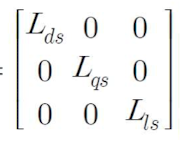 

syms Lds Lqs
Lsw = diag([Lds Lqs Lls])

$$Lsw = \left(\begin{array}{ccc} \mathrm{Lds} & 0 & 0\\ 0 & \mathrm{Lqs} & 0\\ 0 & 0 & \mathrm{Lls} \end{array}\right)$$

Lfw = simplify( T*Lfs )

$$Lfw = \left(\begin{array}{c} \mathrm{Lsf}\\ 0\\ 0 \end{array}\right)$$

syms id iq
Isw = [id; iq; 0]; % dqn current

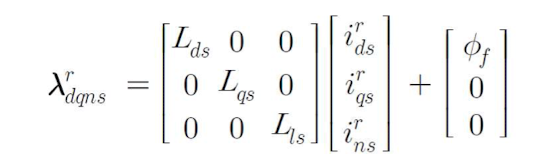

Psw = Lsw*Isw + Lfw; % 문제3.5 SynRM은 Lfw =0, 즉 계자 플럭스가 0이다.

syms P Rs;

Vsw = Rs*Isw + w*J*Psw

$$Vsw = \left(\begin{array}{c} \mathrm{Rs}\,\text{id}-\mathrm{Lqs}\,\mathrm{iq}\,w\\ \mathrm{Rs}\,\mathrm{iq}+w\,\left(\mathrm{Lsf}+\mathrm{Lds}\,\text{id}\right)\\ 0 \end{array}\right)$$

Torque = simplify( 3/2* P*cross(Psw, Isw) )

$$Torque = \left(\begin{array}{c} 0\\ 0\\ \frac{3\,P\,\mathrm{iq}\,\left(\mathrm{Lsf}+\mathrm{Lds}\,\text{id}-\mathrm{Lqs}\,\text{id}\right)}{2} \end{array}\right)$$